Analisis por municipio (selecciona municipio de 1-10)

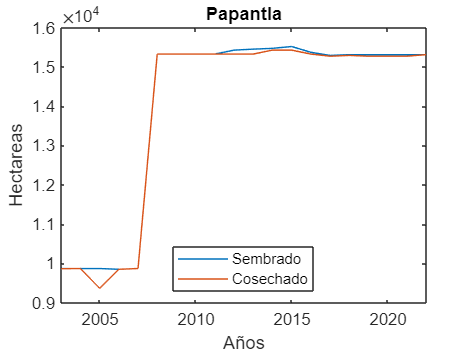

eage_x=2003:2022;
format long;
idx_municipio=4;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
hold on;
plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
title(data_production(idx_municipio).Municipio);
legend("Sembrado", "Cosechado","Location","south");
xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
% ax = gca;
% ax.FontSize=18; 
hold off

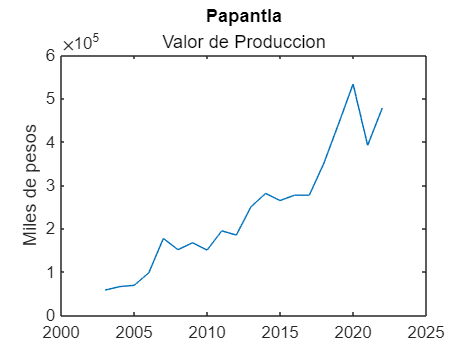


plot(eage_x, data_production(idx_municipio).Valor_Prod)
ylabel("Miles de pesos")
title(data_production(idx_municipio).Municipio,'Valor de Produccion');

## Redes neuronales

% parametros arreglo, area_studio, valor (1 naranja 0 no naranja)
% data_tab_function=f_aplica_formulas(arr_ndvi_sgf,study_area,1)

indxs=find(info_hdf.anio==2022);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);
% data_tab_function=f_aplica_formulas(datos,study_area,1)
data_tab_test=f_aplica_formulas(datos,study_area,1)

data_tab_test = 27227×9 table
         Mediana             Promedio               Moda                 Rango              Desviacion             Minimos              Maximos                Mad            Valor
    _________________    _________________    _________________    _________________    __________________    _________________    _________________    __________________    _____

    0.576861904761905    0.600469565217391    0.438804761904762    0.381266666666667     0.091807287505087    0.438804761904762    0.820071428571429    0.0727092807633451      1  
    0.606333333333333    0.610131262939959    0.483795238095238    0.235033333333333    0.0690635375862339    0.48379523809

Cargar solo los datos requeridos

data_ndvi=data_tab_function(:,1:8);

## Implementacón de las redes neuronales 

% class_result=model_entrenado.predictFcn(data_ndvi);
% class_result=Model_trained.predictFcn(data_ndvi);
class_result=Trained_model.predictFcn(data_ndvi);

area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);

area_clasificada=arr_ndvi_sgf;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## Hectareas encontradas

% 1 PX= 250m X 250m=62500 En hectareas 6.25Has
pix_area=sum(area_naranja,"all")

pix_area = 14907

disp("Hectareas Encontradas")

Hectareas Encontradas



fprintf('%.2f\n', pix_area*6.25);

93168.75


## Hectareas por año

data_result=[];
indice=1;

area_naranja=struct;

for eage=2003:2022
    indxs=find(info_hdf.anio==eage);
    
    datos=arr_ndvi_sgf(:,:,indxs);
    

      data_tab_function=f_aplica_formulas(datos,study_area,1);
%     data_tab_function=f_training_data(datos,study_area,1);


    
    data_ndvi=data_tab_function(:,1:8);
%     data_ndvi=data_tab_function(:,1);


% --------------------------------------------------TEMP
%     [~,~,pix_tam] =size(datos);
%     
%     d_res_tmp=[];
% 
%     for pxi_i=1:pix_tam
%         data_tab_function=f_training_data(datos(:,:,pxi_i),study_area,1);  
%         t_pxi=table2array(data_tab_function(:,1));
%         d_res_tmp=[d_res_tmp,t_pxi];
%     end

% --------------------------------------------------
    class_result=model_entrenado.predictFcn(data_ndvi);

    area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);
    
    areas_naranja.Matriz(indice)={area_naranja(:,:)};
    
%     pix_area=sum(area_naranja,"all");
    pix_area=sum(class_result)
    
    data_result(indice)=pix_area*6.25;
%     data_result(indice)=pix_area;

   indice=indice+1;
end

pix_area =         9286


pix_area =         7648


pix_area =         7516


pix_area =         8175


pix_area =         7068


pix_area =         8899


pix_area =         9319


pix_area =         7690


pix_area =         9777


pix_area =         7480


pix_area =         8497


pix_area =         7669


pix_area =         7486


pix_area =         9385


pix_area =         8614


pix_area =         8195


pix_area =        10964


pix_area =         7151


pix_area =         8212


pix_area =         9619


## Data result

figure 
hold on;

eage_x=2003:2022;
format long;
idx_municipio=10;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
% plot(eage_x, data_production(idx_municipio).Produccion_Ton, 'LineWidth', 2, 'LineStyle', ':','Color','m');

% 
% plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
% title(data_production(idx_municipio).Municipio);
plot(eage_x, data_result, 'LineWidth', 2, 'LineStyle', '--','Color','r')
% legend("Sembrado", "Producción","Red Neuronal","Location","south");
legend("Sembrado","Red Neuronal","Location","south");

title("Comparacion de resultados",data_production(idx_municipio).Municipio);

xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
ax = gca;
ax.FontSize=20; 


[a02,a12,ajuste_2]=f_reglin(1:length(data_result),data_result)

a02 =      5.020325657894737e+04


a12 =      2.380827067669173e+02


ajuste_2 = 1.0e+04 *

   5.044133928571428   5.067942199248120   5.091750469924812   5.115558740601504   5.139367011278195   5.163175281954887   5.186983552631578   5.210791823308270   5.234600093984962   5.258408364661654   5.282216635338346   5.306024906015037   5.329833176691729   5.353641447368421   5.377449718045113   5.401257988721804   5.425066259398497   5.448874530075188   5.472682800751880   5.496491071428571


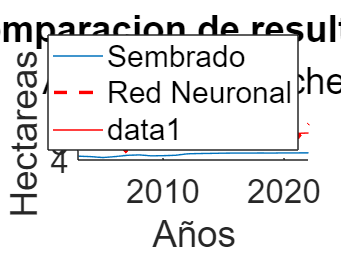


plot(eage_x, ajuste_2,"r")


hold off

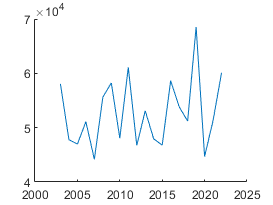


figure
hold on
plot(eage_x,data_result)
hold off

## Calcular el error cuadratico medio 

%
% Calcular el error cuadrático para cada observación
% err_x=immse(data_production(idx_municipio).Superficie_sembrada_Ha,data_result);
% 
% fprintf('El RMSE es: %f\n', err_x);
% fprintf('\n The mean-squared error is %0.4f\n', err_x);
% 
% [a02,a12,ajuste_2]=f_reglin(data_production(idx_municipio).Superficie_sembrada_Ha ,data_result)
% 
% plot(eage_x, ajuste_2,"--")


% Calcular el Error Cuadrático Medio (MSE)
err_x = immse(data_production(idx_municipio).Superficie_sembrada_Ha ,data_result);

disp(err_x)

     1.327659871653550e+08



## Marcar zonas

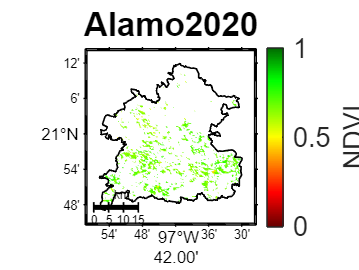

anio=2020;
indxs=find(info_hdf.anio==anio);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);

data_tab_function=f_aplica_formulas(datos,study_area,1);
% data_tab_function=f_training_data(datos,study_area,1);

data_ndvi=data_tab_function(:,1:8);
% data_ndvi=data_tab_function(:,1);

class_result=model_entrenado.predictFcn(data_ndvi);

area_naranja=f_make_area(datos,class_result,study_area);

area_clasificada=datos;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml+anio,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## TEST ELEMENTS

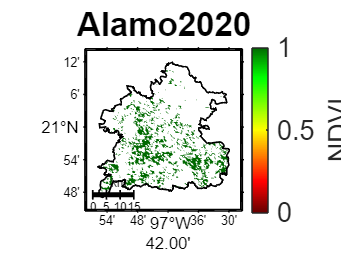

lat_map_x=lat;
lon_map_x=lon;
[h,w]=size(lat_map_x);

area_x=ones(h,w);

area_x(area_naranja==0)=NaN;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_x,archivo_kml+anio,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

VALIDAR SI SON IGUALES

% Perform k-means clustering using specified number of clusters (K value)
K = 3;
[clusterIndices,centroids] = kmeans(X,K);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices,colormap("lines"));
for i2 = 1:numel(h)
    h(i2).DisplayName = strcat("Cluster",h(i2).DisplayName);
end
clear h i2 score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");